%write the starting and ending position
start_pos = 516930

start_pos = 516930

end_pos = (start_pos + 2000)

end_pos = 518930


%write the experiment state and the count (calculation / happy / sad )
state = "Boring" 

state = "Boring"

count = "8"

count = "8"


%calculation (0, 1, 2, .....)
%happy(0, 1, 2, .....)


%write the first three letters of your name
my_name_3 = "mjh"

my_name_3 = "mjh"


%write the name of the file (subject) you want to load
load_file_name = '17201083.txt'

load_file_name = '17201083.txt'



%%%Don't edit unless you know what you are doing
load_file_name_nofmt = erase(load_file_name,'.txt')

load_file_name_nofmt = '17201083'

file_name = state + "_" + load_file_name_nofmt+ "_" + my_name_3 + "_"+ count

file_name = "Boring_17201083_mjh_8"

file_name_csv = file_name + ".csv"

file_name_csv = "Boring_17201083_mjh_8.csv"

file_name_png = file_name + ".png"

file_name_png = "Boring_17201083_mjh_8.png"


x = load(load_file_name)

x =      0     0     0     0     0   432
     1     0     0     0     0   464
     2     0     0     0     0   522
     3     0     0     0     0   583
     4     0     0     0     0   627
     5     0     0     0     0   647
     6     0     0     0     0   653
     7     0     0     0     0   647
     8     0     0     0     0   629
     9     0     0     0     0   607



S=x(:,6);

s = S(start_pos:end_pos)

s =    529
   529
   525
   518
   502
   483
   465
   441
   412
   385


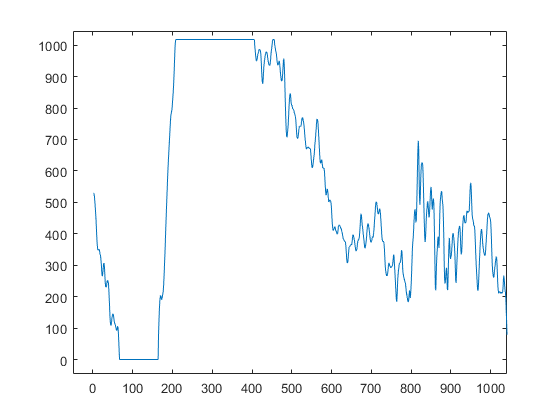

csvwrite(file_name_csv,s)

plot(s);

xlim([-50 1041])
ylim([-46 1045])
print(gcf,file_name_png,'-dpng','-r600');  